MorphData-mush


     HeadArea     HomerFWHMArea    HomerNumber    NeckLength
    __________    _____________    ___________    __________

    3.3942e+05    38433            1.1449         531.3     



Mushroom percentage of spines per cluster


  Columns 1 through 14

   13.4781    6.3534    8.2614    0.6445   13.1940   13.3005    2.7098    5.6379    0.1928    8.2817    0.5075    5.2319   12.5495    2.4663

  Columns 15 through 16

    0.1269    4.1662



MorphData-flat


     HeadArea     HomerFWHMArea    HomerNumber
    __________    _____________    ___________

    2.8626e+05    44099            1.0224     



Stubby percentage of spines per cluster


   34.2379   11.4218   15.4368    0.1592   33.2549    0.7684    0.0208    1.8690



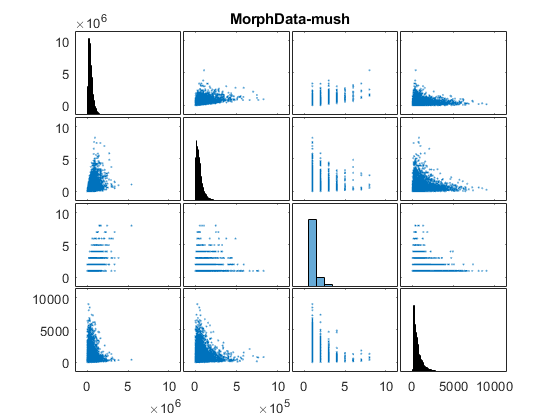

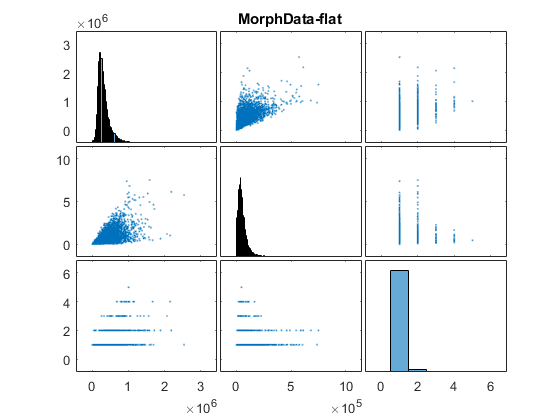

%Determine grouping thresholds
classes = {'mush', 'flat'};
cd 'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\'
% param = {'HeadArea', 'HeadHeight', 'HeadWidth', 'HomerFWHMArea', 'HomerFWHMDioDistance', 'HomerFWHMMajorAxisLength', 'HomerFWHMMinorAxisLength', 'HomerFWHMMeanIntensity', 'HomerNumber', 'NeckLength', 'NeckArea'};
param = {'HeadArea', 'HomerFWHMArea', 'HomerNumber', 'NeckLength'};

for class = 1:numel(classes)
    %     Reading in data and cleanup
    data = load(['MorphData_' classes{class}]);
    field = fieldnames(data);
    data = data.(field{1});
    
    data = data(:, contains(data.Properties.VariableNames, param));
    
    data = standardizeMissing(data,Inf);
    if strcmp(classes{class}, 'flat')
        data.NeckLength = [];
    end
    
    figure
    plotmatrix(table2array(data));
    title(['MorphData-' classes{class}]);
    
    logdata = log10(table2array(data));
    logdata = standardizeMissing(logdata,-Inf); % to account for 0 values, which give Inf after log transform
    logdata = nanmean(logdata,1);
    logdata = 10.^logdata;
    logdata = array2table(logdata,'VariableNames',data.Properties.VariableNames);
    disp(['MorphData-' classes{class}])
    disp(logdata)
    
    % Assign each file to one of the clusters
    idx = zeros(size(data,1),1);
    head_s = data.HeadArea < logdata.HeadArea;
    head_l = data.HeadArea >= logdata.HeadArea;
    homer_s = data.HomerFWHMArea < logdata.HomerFWHMArea;
    homer_l = data.HomerFWHMArea >= logdata.HomerFWHMArea;
    homernum_s = data.HomerNumber < ceil(logdata.HomerNumber); %HomerNumber is integer. Use ceiling here to make the threshold also integer. Since I use < I want to use ceiling to have the threshold of 1.0224 turned into 2, so everything below 2 (0-1) is part of the small homernumber cluster.
    homernum_l = data.HomerNumber >= ceil(logdata.HomerNumber);
    %     For mushroom, also create the neck classifier
    if class==1
        neck_s = data.NeckLength < logdata.NeckLength;
        neck_l = data.NeckLength >= logdata.NeckLength;
    end
    
    if class==1
        idx(all([head_s,homer_s,homernum_s,neck_s],2)) = 1;
        idx(all([head_l,homer_s,homernum_s,neck_s],2)) = 2;
        idx(all([head_s,homer_l,homernum_s,neck_s],2)) = 3;
        idx(all([head_s,homer_s,homernum_l,neck_s],2)) = 4;
        idx(all([head_s,homer_s,homernum_s,neck_l],2)) = 5;
        idx(all([head_l,homer_l,homernum_s,neck_s],2)) = 6;
        idx(all([head_l,homer_s,homernum_l,neck_s],2)) = 7;
        idx(all([head_l,homer_s,homernum_s,neck_l],2)) = 8;
        idx(all([head_s,homer_l,homernum_l,neck_s],2)) = 9;
        idx(all([head_s,homer_l,homernum_s,neck_l],2)) = 10;
        idx(all([head_s,homer_s,homernum_l,neck_l],2)) = 11;
        idx(all([head_l,homer_l,homernum_l,neck_s],2)) = 12;
        idx(all([head_l,homer_l,homernum_s,neck_l],2)) = 13;
        idx(all([head_l,homer_s,homernum_l,neck_l],2)) = 14;
        idx(all([head_s,homer_l,homernum_l,neck_l],2)) = 15;
        idx(all([head_l,homer_l,homernum_l,neck_l],2)) = 16;
        disp('Mushroom percentage of spines per cluster')
        disp(sum(idx==1:16)/size(idx,1)*100)
        csvwrite('manualclusters_mush.csv',idx)
    end
    
    if class==2
        idx(all([head_s,homer_s,homernum_s],2)) = 1;
        idx(all([head_l,homer_s,homernum_s],2)) = 2;
        idx(all([head_s,homer_l,homernum_s],2)) = 3;
        idx(all([head_s,homer_s,homernum_l],2)) = 4;
        idx(all([head_l,homer_l,homernum_s],2)) = 5;
        idx(all([head_l,homer_s,homernum_l],2)) = 6;
        idx(all([head_s,homer_l,homernum_l],2)) = 7;
        idx(all([head_l,homer_l,homernum_l],2)) = 8;
        disp('Stubby percentage of spines per cluster')
        disp(sum(idx==1:8)/size(idx,1)*100)
        csvwrite('manualclusters_flat.csv',idx)
    end
end

Error using save
Must be a string scalar or character vector.

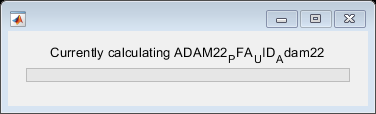

% Create cluster averages
addpath(genpath('Z:\user\mhelm1\Programming\export_fig'));
addpath(genpath('Z:\user\mhelm1\Programming\MatLab\Colormaps'));
set(0, 'DefaultFigureColormap', inferno())
clear idx

for class = 1:numel(classes)
    if strcmp(classes{class},'mush')
        idx = csvread('manualclusters_mush.csv');
        ProteinID=load('ProteinID_mush.mat'); ProteinID=ProteinID.ProteinID_mush;
        SpotFiles=load('SpotFiles_mush.mat'); SpotFiles=SpotFiles.SpotFiles_mush;
        
    elseif strcmp(classes{class},'flat')
        idx = csvread('manualclusters_flat.csv');
        ProteinID=load('ProteinID_flat.mat'); ProteinID=ProteinID.ProteinID_flat;
        SpotFiles=load('SpotFiles_flat.mat'); SpotFiles=SpotFiles.SpotFiles_flat;
    end
    
    proteinnames=ProteinID.Properties.VariableNames;
    w=waitbar(0,'Please wait...');
    
    for protein=1:size(proteinnames,2)
        waitbar(protein/size(proteinnames,2),w,['Currently calculating ' proteinnames{protein}]);
        
        %     Create a results folder for the protein
        if ~exist(['ClusterAverages' filesep proteinnames{protein}],'dir')
            mkdir(['ClusterAverages' filesep proteinnames{protein}]);
        end
        
        clear mess* spots cluster_id path coord* lib* dio* homer* sted*
        
        %     get the spot files and cluster memberships of spines analyzed for this protein
        spots=SpotFiles(ProteinID.(proteinnames{protein})==1);
        cluster_id=idx(ProteinID.(proteinnames{protein})==1);
        
        %% Create a library that links a spot file to its corresponding aligned images.
        
        % get the two folder names from the spot files
        path=regexp(spots,'\','split');
        path=cellfun(@(x) x(end-1),path,'UniformOutput',0);
        path=[path{:}]';
        path=unique(path,'stable');
      
        coord1=load(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'coordinates.mat']);
        coord1=coord1.coordinates;
        
        [~,mess_spots_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep '*_spots*.txt']);
        [~,order]=sort({mess_spots_rep1.Name});mess_spots_rep1=mess_spots_rep1(order);order=[]; %sort to avoid unordered spot files due to server bugs
        mess_spots_rep1=mess_spots_rep1(coord1.classification==class);
        classification1=coord1.classification;
        classification1(classification1==4)=[];
        [~,mess_dio_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep '*dio_aligned_150px_myfilt*.txt']);
        mess_dio_rep1=natsort({mess_dio_rep1.Name});
        mess_dio_rep1(classification1~=class)=[];
        [~,mess_homer_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'homer_aligned_150px_myfilt*.txt']);
        mess_homer_rep1=natsort({mess_homer_rep1.Name});
        mess_homer_rep1(classification1~=class)=[];
        [~,mess_sted_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'sted_aligned_150px_myfilt*.txt']);
        mess_sted_rep1=natsort({mess_sted_rep1.Name});
        mess_sted_rep1(classification1~=class)=[];
        lib_rep1=cat(2,{mess_spots_rep1.Name}',mess_dio_rep1',mess_homer_rep1',mess_sted_rep1');
        
        
        coord2=load(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'coordinates.mat']);
        coord2=coord2.coordinates;
        
        [~,mess_spots_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep '*_spots*.txt']);
        [~,order]=sort({mess_spots_rep2.Name});mess_spots_rep2=mess_spots_rep2(order);order=[]; %sort to avoid unordered spot files due to server bugs
        mess_spots_rep2=mess_spots_rep2(coord2.classification==class);
        classification2=coord2.classification;
        classification2(classification2==4)=[];
        [~,mess_dio_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'dio_aligned_150px_myfilt*.txt']);
        mess_dio_rep2=natsort({mess_dio_rep2.Name});
        mess_dio_rep2(classification2~=class)=[];
        [~,mess_homer_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'homer_aligned_150px_myfilt*.txt']);
        mess_homer_rep2=natsort({mess_homer_rep2.Name});
        mess_homer_rep2(classification2~=class)=[];
        [~,mess_sted_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'sted_aligned_150px_myfilt*.txt']);
        mess_sted_rep2=natsort({mess_sted_rep2.Name});
        mess_sted_rep2(classification2~=class)=[];
        lib_rep2=cat(2,{mess_spots_rep2.Name}',mess_dio_rep2',mess_homer_rep2',mess_sted_rep2');
        lib=cat(1,lib_rep1,lib_rep2);
        
        
        %% Loop over the cluster IDs and find all spots that correspond to the cluster for the protein. Average them
        for i=1:numel(unique(cluster_id))
            cluster_idx = cluster_id(i);
            spots_cluster=spots(cluster_id==cluster_idx);
            dio=zeros(151,151,numel(spots_cluster));
            homer=zeros(151,151,numel(spots_cluster));
            sted=zeros(151,151,numel(spots_cluster));
            for j=1:numel(spots_cluster)
                spots_avg_num=find(contains(lib(:,1),spots_cluster{j}));
                dio(:,:,j)=dlmread(lib{spots_avg_num,2});
                homer(:,:,j)=dlmread(lib{spots_avg_num,3});
                sted(:,:,j)=dlmread(lib{spots_avg_num,4});
            end
            
            save(['ClusterAverages' filesep proteinnames{protein} filesep 'CombinedImageStack_' classes{class} '_dio_cluster' num2str(cluster_idx) '.mat'],'dio');
            save(['ClusterAverages' filesep proteinnames{protein} filesep 'CombinedImageStack_' classes{class} '_homer_cluster' num2str(cluster_idx) '.mat'],'homer');
            save(['ClusterAverages' filesep proteinnames{protein} filesep 'CombinedImageStack_' classes{class} '_sted_cluster' num2str(cluster_idx) '.mat'],'sted');
            
            dio_avg=mean(dio,3);
            homer_avg=mean(homer,3);
            sted_avg=mean(sted,3);
            
            dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_dio_cluster' num2str(cluster_idx) '.txt'],dio_avg);
            dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_homer_cluster' num2str(cluster_idx) '.txt'],homer_avg);
            dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_sted_cluster' num2str(cluster_idx) '.txt'],sted_avg);
            
            f1=figure('Visible','off');
            imagesc(dio_avg);
            axis equal;
            axis off;
            export_fig(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_dio_cluster' num2str(cluster_idx)], '-png', '-pdf', '-q101', '-transparent');
            close(f1);
            
            f1=figure('Visible','off');
            imagesc(homer_avg);
            axis equal;
            axis off;
            export_fig(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_homer_cluster' num2str(cluster_idx)], '-png', '-pdf', '-q101', '-transparent');
            close(f1);
            
            f1=figure('Visible','off');
            imagesc(sted_avg);
            axis equal;
            axis off;
            export_fig(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_sted_cluster' num2str(cluster_idx)], '-png', '-pdf', '-q101', '-transparent');
            close(f1)
        end
    end
end

%Analyse cluster averages
clear all
classes = {'mush', 'flat'};
zones_mush=double(imread('Z:\user\mhelm1\Nanomap_Analysis\Matlab\ZoneAnalysis\mushroom_zones_plus_background.tif'));
zones_flat=double(imread('Z:\user\mhelm1\Nanomap_Analysis\Matlab\ZoneAnalysis\flat_thin_zones_plus_background.tif'));
zones_mush_avg = dlmread('Z:\user\mhelm1\Nanomap_Analysis\Matlab\ZoneAnalysis\Mush_ZoneEnrichment_avg_nonnormalized.txt');
zones_flat_avg = dlmread('Z:\user\mhelm1\Nanomap_Analysis\Matlab\ZoneAnalysis\Flat_ZoneEnrichment_avg_nonnormalized.txt');

cd_path='Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages'
folders = getfolders(cd_path);

for folder = 1:numel(folders)
    cd([cd_path filesep folders{folder}])
    T_mush=table();
    T_flat=table();
    T_mush_sd=table();
    T_flat_sd=table();
    T_mush_sem=table();
    T_flat_sem=table();
    
    for class = 1:numel(classes)
        clusters = dir(['CombinedImageStack_' classes{class} '_sted_cluster*.txt']);
        clusters = {clusters.name};
        
        if strcmp(classes{class},'mush')
            zone_def = zones_mush;
        elseif strcmp(classes{class},'flat')
            zone_def = zones_flat;
        else
            disp('Error in class selection!')
            break
        end
        
        for cluster = 1:numel(clusters)
            load(cluster{clusters})
            
            if strcmp(classes{class},'mush')
                
                for zone=1:15%max(zones_mush(:))
                    temp=[];
                    for k=1:size(sted,3)
                        z=sted(:,:,k);
                        temp=cat(1,temp,nansum(z(zones_def==zone))/nansum(z(zones_def<16)));
                    end
                    temp=temp/sum(zones_def(:)==zone);
                    temp=(temp-zones_mush_avg(zone))/zones_mush_avg(zone);
                    T_mush_foldoveravg{cluster,zone}=nanmean(temp);
                    T_mush_foldoveravg_sd{cluster,zone}=nanstd(temp);
                    T_mush_foldoveravg_sem{cluster,zone}=nanstd(temp)/sqrt(length(temp));
                end

            elseif strcmp(classes{class},'flat')
                for zone=1:11%max(zones_flat(:))
                    temp=[];
                    for k=1:size(sted_flat,3)
                        z=sted_flat(:,:,k);
                        %                 temp=cat(1,temp,z(zones_flat==j));
                        temp=cat(1,temp,nansum(z(zones_flat==zone))/nansum(z(zones_flat<16)));
                    end
                    temp=temp/sum(zones_flat(:)==zone);
                    temp=(temp-zones_flat_avg(zone))/zones_flat_avg(zone);
                    T_flat_foldoveravg{cluster,zone}=nanmean(temp);
                    T_flat_foldoveravg_sd{cluster,zone}=nanstd(temp);
                    T_flat_foldoveravg_sem{cluster,zone}=nanstd(temp)/sqrt(length(temp));
                end
            end

        end
    end
    
    cluster_idx = cellfun(@(x)regexp(x,'(?<=cluster)\d+','match'),clusters);
    cluster_idx = cellfun(@(x)['cluster' x],cluster_idx,'UniformOutput',false);
    
    T_mush_foldoveravg.Properties.RowNames=cluster_idx;
    T_flat_foldoveravg.Properties.RowNames=cluster_idx;
    T_mush_foldoveravg_sd.Properties.RowNames=cluster_idx;
    T_flat_foldoveravg_sd.Properties.RowNames=cluster_idx;
    T_mush_foldoveravg_sem.Properties.RowNames=cluster_idx;
    T_flat_foldoveravg_sem.Properties.RowNames=cluster_idx;
    
    T_mush_foldoveravg.Properties.VariableNames=sprintfc('Zone%i',1:15);
    T_flat_foldoveravg.Properties.VariableNames=sprintfc('Zone%i',1:11);
    T_mush_foldoveravg_sd.Properties.VariableNames=sprintfc('Zone%i',1:15);
    T_flat_foldoveravg_sd.Properties.VariableNames=sprintfc('Zone%i',1:11);
    T_mush_foldoveravg_sem.Properties.VariableNames=sprintfc('Zone%i',1:15);
    T_flat_foldoveravg_sem.Properties.VariableNames=sprintfc('Zone%i',1:11);
    
    save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg.mat'],'T_mush_foldoveravg');
    save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg.mat'],'T_flat_foldoveravg');
    save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg_sd.mat'],'T_mush_foldoveravg_sd');
    save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg_sd.mat'],'T_flat_foldoveravg_sd');
    save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg_sem.mat'],'T_mush_foldoveravg_sem');
    save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg_sem.mat'],'T_flat_foldoveravg_sem');
    
    writetable(T_mush_foldoveravg,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','data');
    writetable(T_flat_foldoveravg,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','data');
    writetable(T_mush_foldoveravg_sd,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','sd');
    writetable(T_flat_foldoveravg_sd,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','sd');
    writetable(T_mush_foldoveravg_sem,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','sem');
    writetable(T_flat_foldoveravg_sem,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','sem');
end